# Hilbert Transform

## What is Hilbert Transform?

The discrete Hilbert transform is a process used to generate complex-valued signals from real-valued signals.

It is a method for extracting the magnitude and phase information from a real-valued signal like a EEG data:

Notation used to define the continuous Hilbert transform:

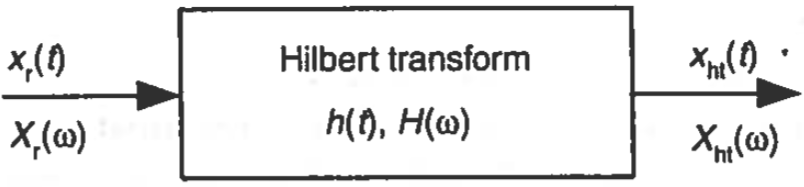

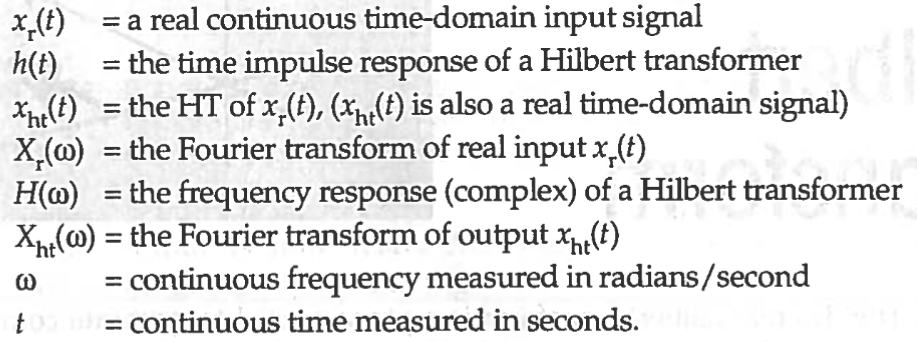

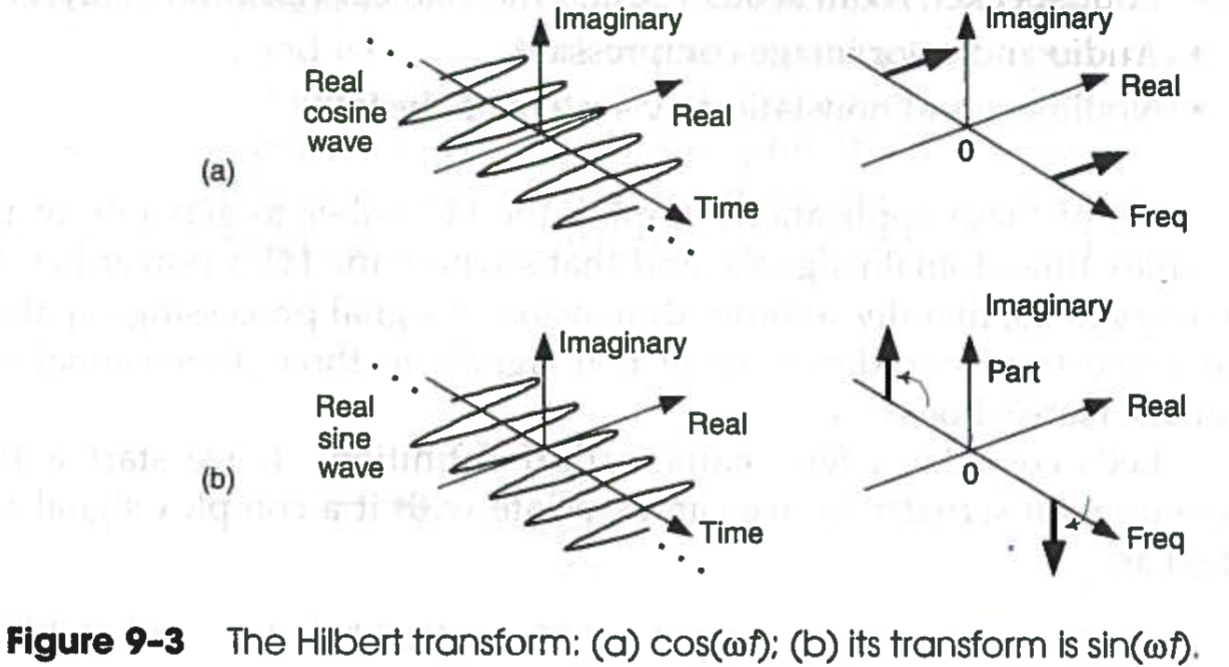

### Why do we need it?

Typically, we start with a real-valued signal which can be conceptualised as:

        
$$x_r \left(t\right)=A\;\mathrm{cos}\left(\omega \;t\right)$$


Given a real-value signal, we cannot estimate or extract the phase angle and the power. What we need to represent the signal as a complex sinusoid using Euler's formula:

        
$$x_c \left(t\right)=A\;e^{j\omega t}$$


        
$$x_c \left(t\right)=A\;\mathrm{cos}\left(\omega \;t\right)+j\;A\;\mathrm{sin}\left(\omega t\right)$$


        
$$x_c \left(t\right)=x_r \left(t\right)+j\;x_i \left(t\right)$$


where 

- $x_c \left(t\right)$ is known as an *analytic signal* because it has no negative-frequency spectral components. This means that $X_c \left(e^{j\omega } \right)$ is zero over the negative frequency range. This is also known as a *one-sided spectrum*.

- $j\;x_i \left(t\right)$ is called the *phase-quadrature component*.

Using complex signals of the real signals simplifies and improves the performance of many signal processing operations.

### Real Signals as Complex Exponentials

A real-valued signal can be seen as a a single frequency phasor (red) that is composed of the sum of two phasors:

- a positive frequency phasor (blue) rotates counter-clockwise

- a negative frequency phasor (green) rotates clockwise

        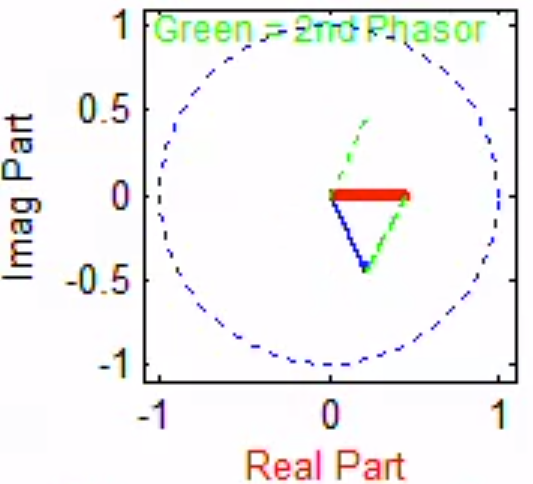           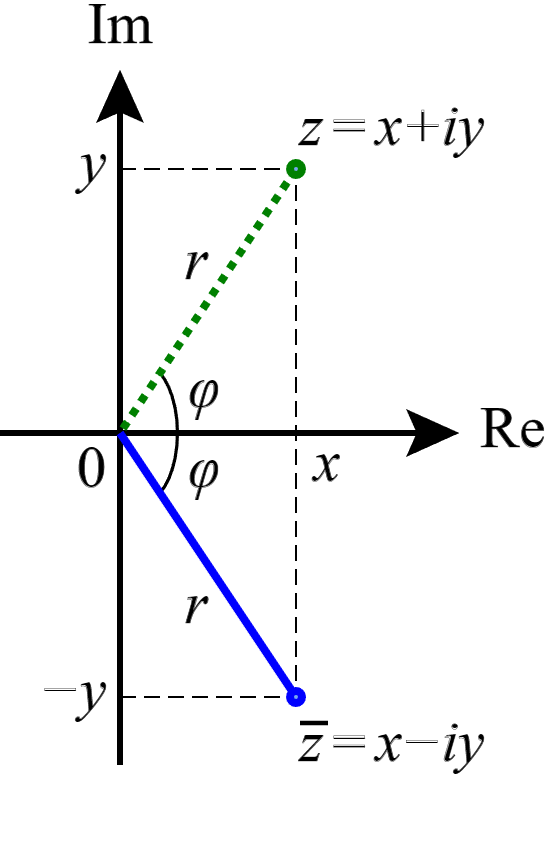

If we project the sum of the two phasors in the real part, we get the red phasor. However, if we project the sum into the imaginary part, the two phasors cancel out one another and we get zero imaginary component.

This means that a real-valued signal has two complex exponentials (complex conjugate phasors) rotating in oppsite directions. The real parts are in phase and sum together, the imaginary parts are opposite polarity, and cancel out, which leaves only a real sinusoid as a result. The negative and positive frequency components ***are*** both necessary to produce the real signal.

A real cosine signal $x_r \left(t\right)=A\;\mathrm{cos}\left(\omega_0 t+\phi \right)$ can be expressed in terms of two complex exponentials using Eulers formula:

        
$$x_r \left(t\right)=A\;\mathrm{cos}\left(\omega_0 t+\phi \right)\;$$


        
$$x_r \left(t\right)=A\;\left(\frac{e^{j\left(\omega t+\phi \right)} +e^{-j\left(\omega +\phi \right)} }{2}\right)\;$$


        
$$x_r \left(t\right)=A\;\left(\frac{1}{2}e^{j\left(\omega t+\phi \right)} +\frac{1}{2}e^{-j\left(\omega t+\phi \right)} \right)\;$$


        
$$x_r \left(t\right)=A\;\left(\frac{1}{2}e^{j\phi } e^{j\omega t} +\frac{1}{2}e^{-j\phi } e^{-j\omega t} \right)\;$$


        $x_r \left(t\right)=\frac{1}{2}Xe^{j\omega t} +\frac{1}{2}X^* e^{-j\omega t} \;$ where $X=Ae^{j\phi }$ and $X^* =Ae^{-j\phi }$

where $X^*$ is complex conjucate of the phasor $X$. This shows that a real-valued signal with frequency $\omega \;$ is actually composed for a positive frequency $+\omega$ complex exponential and a negative frequency $-\omega$ complex exponential.

### Quarter Cycle Shift

The phase-quadrature component can be obtained by a 90 degree (*quarter-cycle*) shift on the complex plan. 

The Hilbert transform of $\mathrm{cos}\left(\theta \right)$ is $\mathrm{sin}\left(\theta \right)$ i.e., a quarter-cycle shift.

        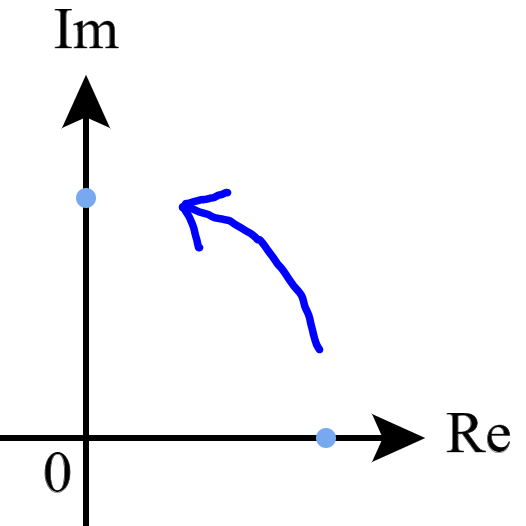

The Hilbert transform rotates the Fourier coefficients in the complex space which converts the real components into the imaginary component. The quarter-cycle shifted signal is then added to the original signal.

In other words, a Hilbert transform takes each frequency component present in the original signal and shifts its phase by $-\frac{\pi }{2}$.

For a continous time signal $x_r \left(t\right)$, the Hilbert transform is defined as:

        $x_{\mathrm{ht}} \left(t\right)=x_r \left(t\right)*\frac{1}{\pi t}$ where $*$ is the convolution operation

We can see the Hilbert transform as a FIR filter with the impulse response $h\left(t\right)=\frac{1}{\pi t}$

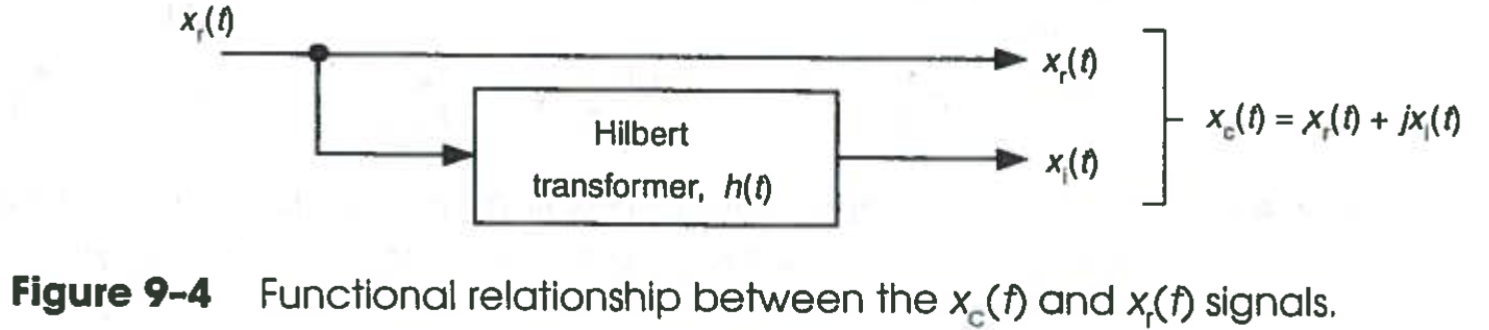

### Table of selected Hilbert transforms

In the following table, the frequency parameter $\omega$ is real. 

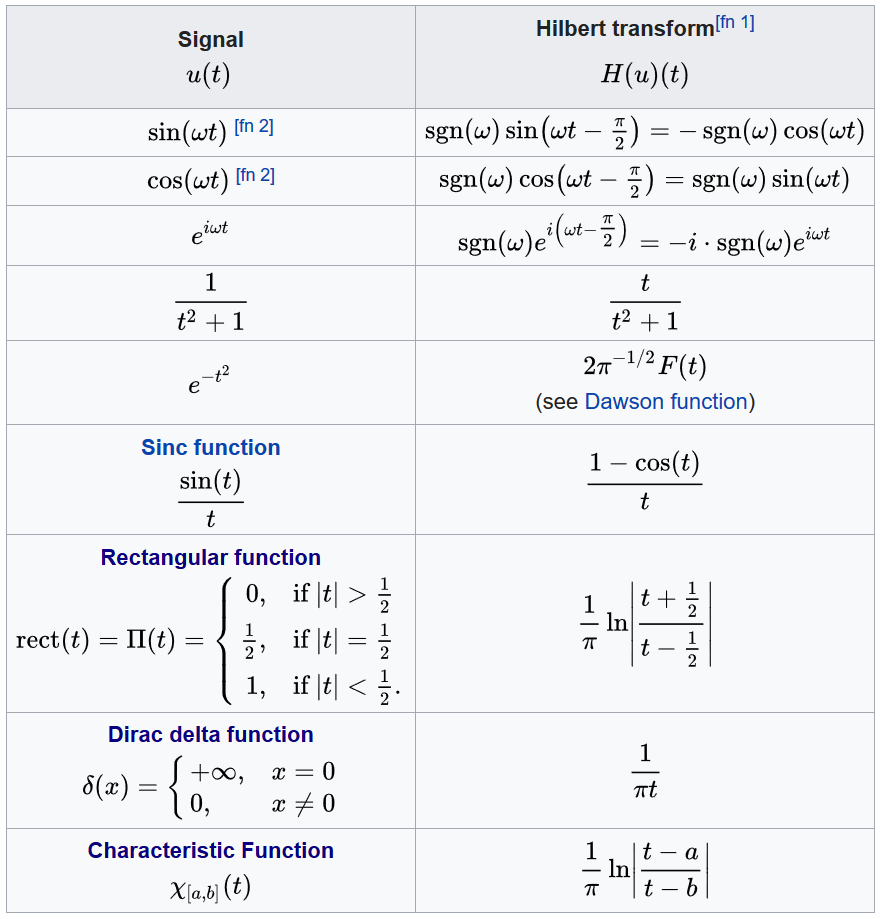

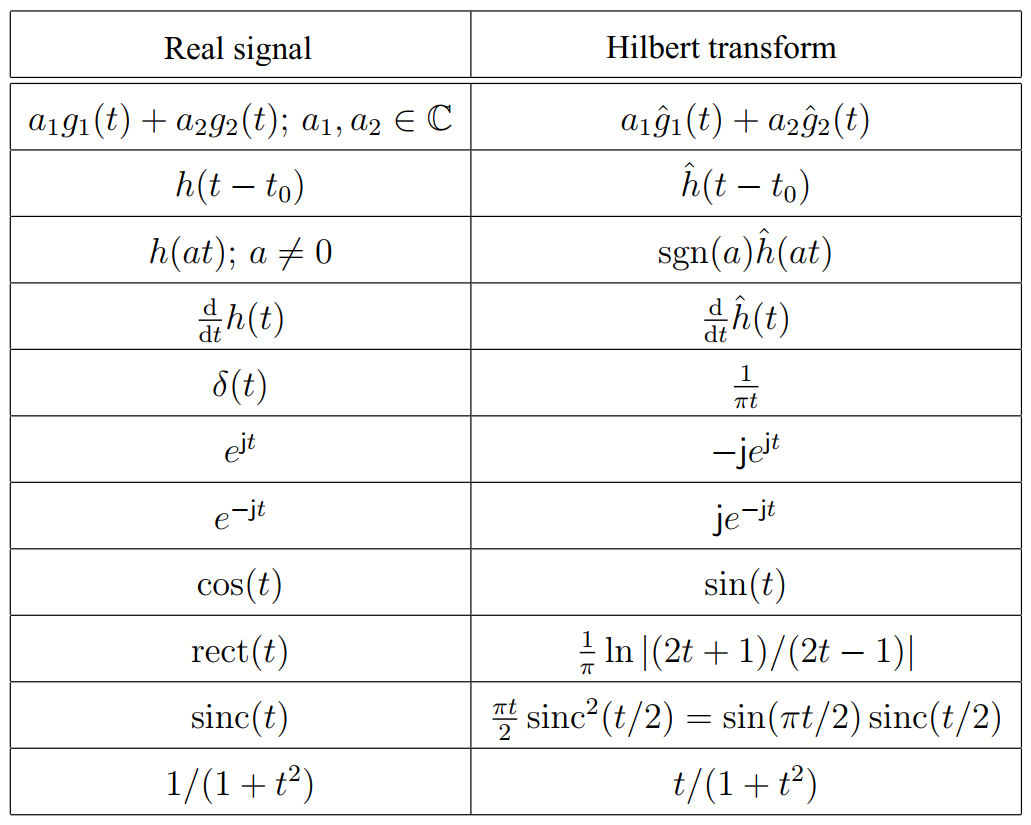

### Properties of the Hilbert transform

**(1)** A signal $x_r \left(t\right)$ and its Hilbert transform $x_i \left(t\right)$ have the **same power density spectrum**.

**(2)** A signal $x_r \left(t\right)$ and its Hilbert transform $x_i \left(t\right)$ have the **same autocorrelation function**.

**(3)** A signal $x_r \left(t\right)$ and its Hilbert transform $x_i \left(t\right)$ are mutually orthogonal so we can write: 

        
$$\int_{-\infty }^{\infty } x_r \left(t\right)x_i \left(t\right)\;\mathrm{dt}=0$$


**(4)** The effect of applying the Hilbert transform twice on a zero mean signal $x_r \left(t\right)$ is:

        
$$H\left\lbrack H\left\lbrack x_r \left(t\right)\right\rbrack \right\rbrack =-x_r \left(t\right)$$


For example, suppose $x_r \left(t\right)=\mathrm{cos}\left(t\right)$. Computing the Hilbert transform we get:

         
$$H\left\lbrack \mathrm{cos}\left(t\right)\right\rbrack =\mathrm{cos}\left(t-\frac{\pi }{2}\right)$$


Computing the Hilber transform again, we get:

         
$$H\left\lbrack \cos \left(t-\frac{\pi }{2}\right)\right\rbrack =\cos \left(t-\frac{\pi }{2}-\frac{\pi }{2}\right)$$


         
$$H\left\lbrack \cos \left(t-\frac{\pi }{2}\right)\right\rbrack =\cos \left(t-\pi \right)$$


         
$$H\left\lbrack \cos \left(t-\frac{\pi }{2}\right)\right\rbrack =-\cos \left(t\right)$$


**(5)** The energy of a Hilbert transform $x_i \left(t\right)$ is the same as the energy of the original signal $x_r \left(t\right)$. Hilbert Transform does not changes the magnitude of the input signal hence the energy is invariant

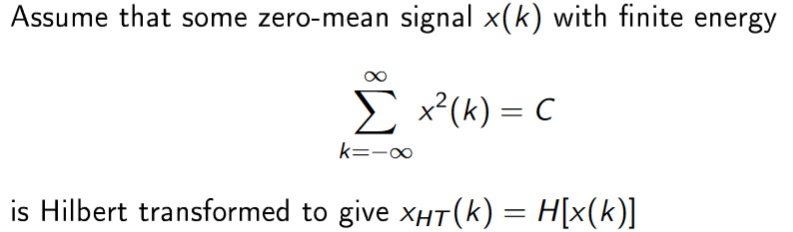

Example:

        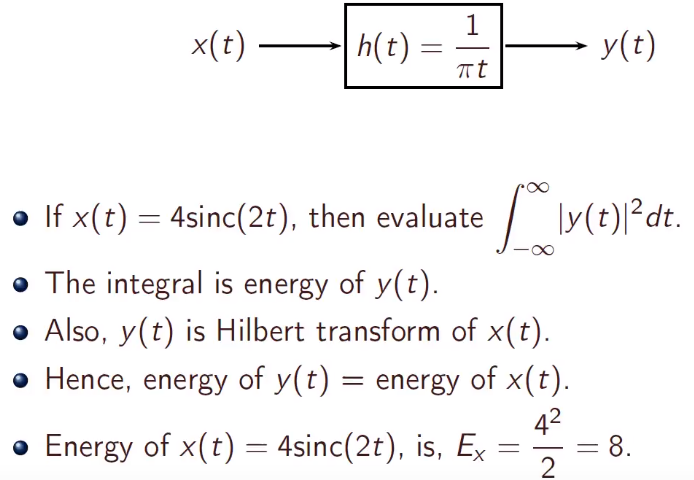

**(6)** The inverse Hilbert transform is $H^{-1} \left\lbrack x_r \left(t\right)\right\rbrack =-H\left\lbrack x_r \left(t\right)\right\rbrack$:

        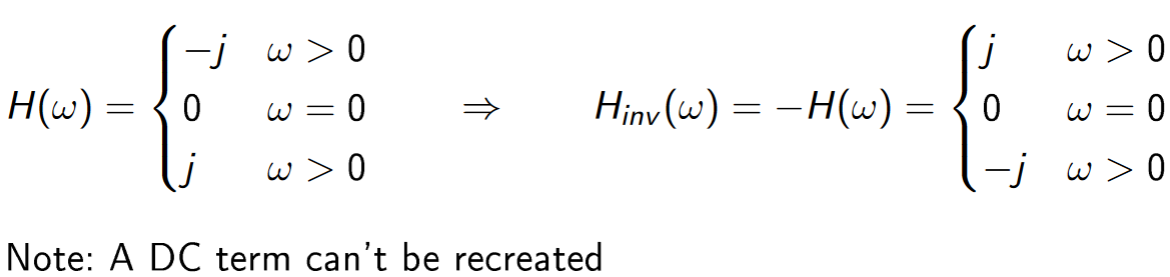

### Envelope Extraction using Hilbert transform

clear variables;

The books states: If a real sinewave $x_r \left(t\right)$ is amplitude modulated so its envelope contains information, then we can measure the instantaneous envelope $E\left(t\right)$ values from an analytic version of the signal using the Equation 9-4:

        

Equation 9-4 states that the envelope of the signal is equal to magnitude of $x_c \left(t\right)$.

In MATLAB the complex magnitude of a signal can be computed with the `abs` function. 

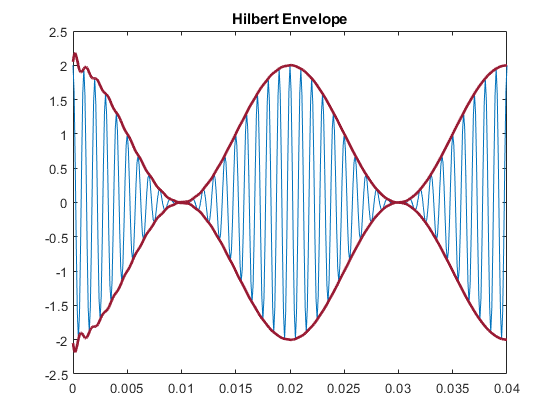

t = 0:1e-4:0.1;
x = (1+cos(2*pi*50*t)).*cos(2*pi*1000*t);

y = hilbert(x);
env = abs(y);
plot_param = {'Color', [0.6 0.1 0.2],'Linewidth',2}; 

plot(t,x)
hold on
plot(t,[-1;1]*env,plot_param{:})
hold off
xlim([0 0.04])
title('Hilbert Envelope')

## FFT-based Hilbert transform

clear variables;

The FFT-based Hilbert transform can be implemented as three steps:

- Take the FFT of a time-series signal

- Rotate the Fourier coefficients

- Take the inverse FFT of the rotated Fourier coefficients to get a time-series signal

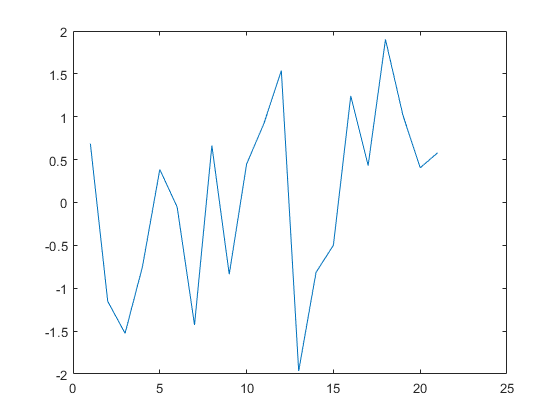

n = 21;

% Generate a signal
x = randn(n, 1);
plot(x)

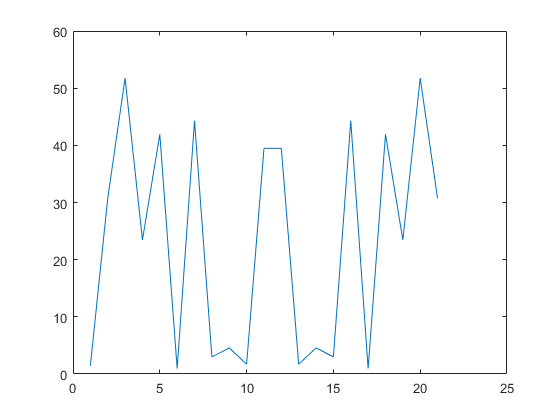



% Step 1: Take the FFT
f = fft(x);

plot(f.*conj(f))

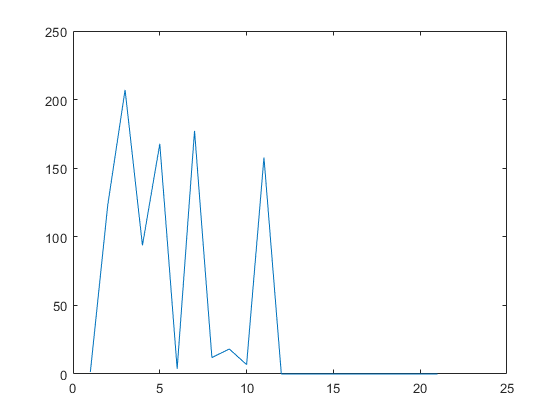


% Create a copy of the Fourier coefficients
complexf = 1i*f;

% Identify the indices for the positive and negative frequencies
% because they are rotated in different ways.
pos_freq_idx = 2:floor(n/2) + mod(n, 2);
neg_freq_idx = ceil(n/2) + 1 + ~mod(n, 2):n;

% Rotate the Fourier coefficients by computing i*A*sin(wt) component.
% Note! Positive frequencies are rotated counter-clockwise while
% negative frequencies are rotated clockwise.
f(pos_freq_idx) = f(pos_freq_idx) + -1i*complexf(pos_freq_idx);
f(neg_freq_idx) = f(neg_freq_idx) +  1i*complexf(neg_freq_idx);

plot(f.*conj(f))

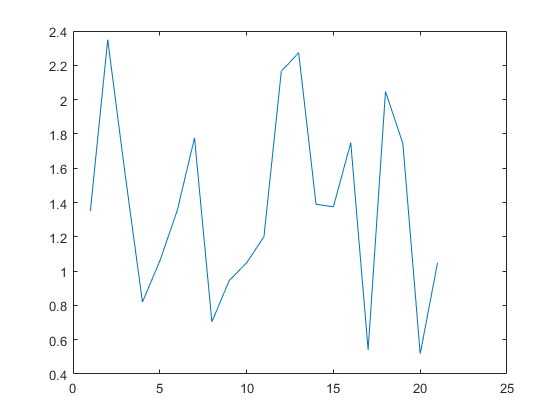


hilbert_x = ifft(f);

plot(abs(hilbert_x))

## Is the Hilbert transform of a triangular wave signal is another triangular wave signal?

Answer: FALSE.

The Hilbert transform rotates the Fourier coefficients in the complex space which converts the real components into the imaginary component. The quarter-cycle shifted signal is then added to the original signal. In other words, a Hilbert transform takes each frequency component present in the original signal and shifts its phase by $-\frac{\pi }{2}$.

The Hilbert transform of $\mathrm{cos}\left(\theta \right)$ is $\mathrm{sin}\left(\theta \right)$ i.e., a quarter-cycle shift.

        

A triangular wave signal can thought of being composed of multiple frequency component. If each of these are shifted by 90 degrees then result is not a triangular wave signal.

We can experiment with it.

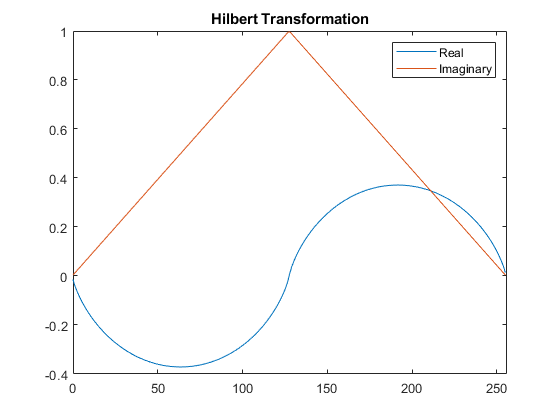

N = 256;
n = 0:N-1;
xr = triang(256);
x = hilbert(xr);
plot(n, imag(x), n, real(x))
legend('Real','Imaginary')
title('Hilbert Transformation')
xlim([0, N])

## ADSI Problem 7.1: Study the hilbert function in MATLAB

A tremendous amount of functionality is found in MATLABs toolboxes and Hilbert transforms are no exception. Type doc hilbert in MATLAB and read the documentation.  

doc hilbert

## ADSI Problem 7.2: Hilbert transform of a cosine signal

*A continuous time signal is given by *$x\left(t\right)=4+3\mathrm{cos}\left(\omega t\right)$*. What is the Hilbert transform of this signal?  *


$$H\left\lbrack 4+3\;\mathrm{cos}\left(\omega t\right)\right\rbrack =H\left\lbrack 4\right\rbrack +3H\left\lbrack \mathrm{cos}\left(\omega t\right)\right\rbrack$$


                            
$$=0+3\textrm{sgn}\left(\omega \right)\sin \left(\omega t\right)$$
 

## [✔] ADSI Problem 7.3: One-sided spectrum of analytical signals

clear variables;

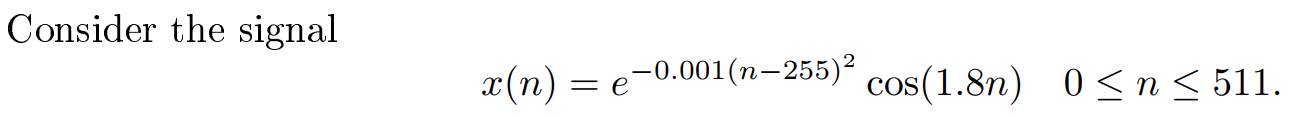

*Calculate the analytical signal in MATLAB and check that the spectrum is one-sided as expected.  *

Recall that we start with a real-valued signal $x_r \left(t\right)$ and we want we need to represent the signal as a complex sinusoid:

        
$$x_c \left(t\right)=x_r \left(t\right)+j\;x_i \left(t\right)$$


$x_c \left(t\right)$ is known as an ***analytic signal*** because it has no negative-frequency spectral components.

To show that the spectrum is one-sided, we have to show that the frequency response $X_c \left(e^{j\omega } \right)$ is zero over the negative frequency range. 

We can do this by estimating the power spectrum density (PSD) of the analytical signal using the periodogram.

In the MATLAB plot, the normalised **positive frequency range** is [0, 1] whereas the **negative frequency range** is between 1 and 2. Notice there is no power spikes in the negative frequency range, only noise.

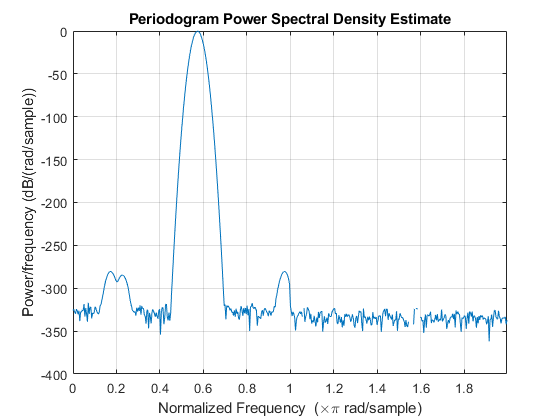

n = (0:511)';
x = exp(-0.001.*(n-225).^2).*cos(1.8*n);

% Compute the analytic signal of the real signal x(n)
y = hilbert(x);

% Compute and plot the PSD estimate
periodogram(y)

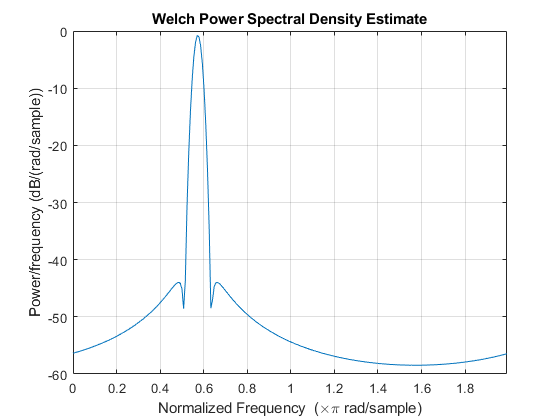

% PSD estimate using the Welch method
pwelch(y)

## [✔] ADSI Problem 7.4: Swept sine wave

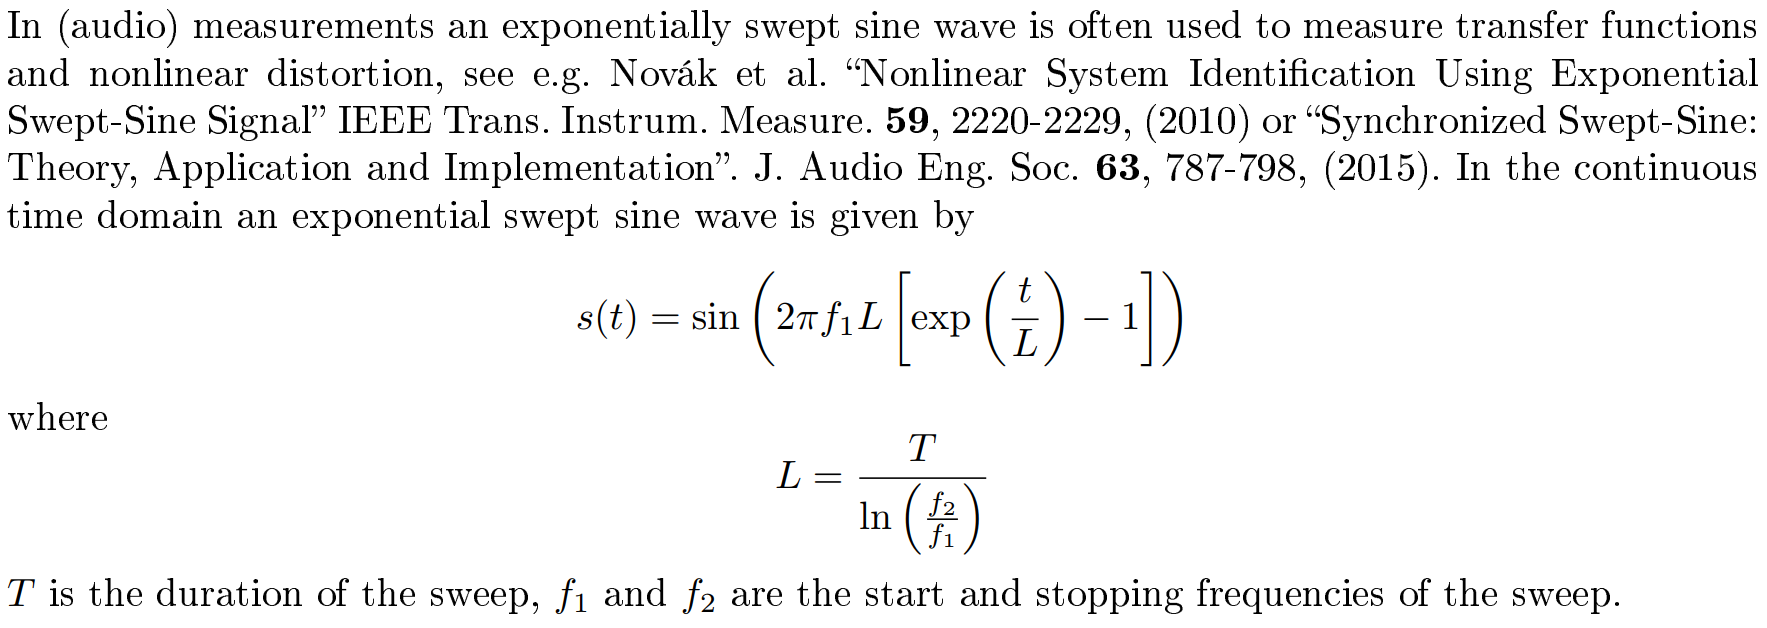

clear variables;

### [✔] 1. Design swept sine signal

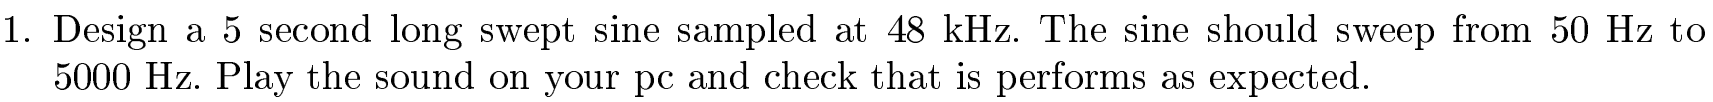

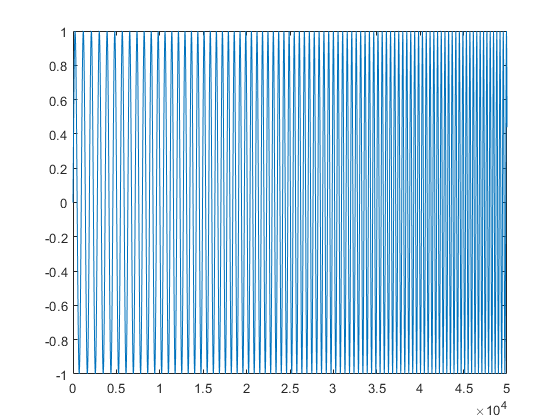

Ts = 48000;  % Sampling rate
f1 = 50;     % Starting 1/frequency
f2 = 5000;   % Stopping 1/frequency
T = 5*Ts;    % Duration of the sweep
L = T / log(f2/f1);

n = 0:T-1;
s = sin(2*pi * f1 * L * (exp(n/L) - 1) / Ts);

% Write to file 
% audiowrite('swept_sine.wav', s, Ts);

% Play sound
soundsc(s, Ts);

% Plot it
plot(n, s)
xlim([0, 50000]);

### [✔] 2. Compute instantaneous frequency

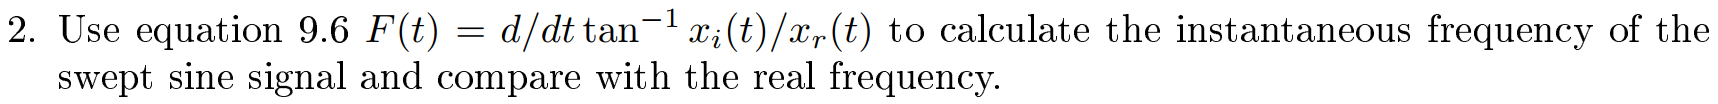

        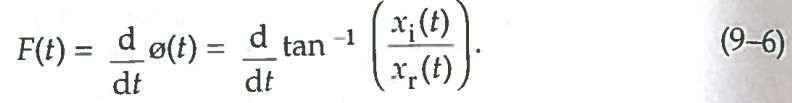

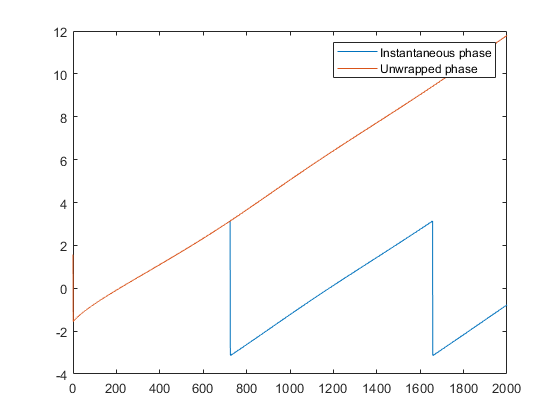

s_c = hilbert(s);  % Compute the analytic signal

% The instantaneous phase can be computed using MATLAB's angle function
inst_phase = angle(s_c);
plot(n, inst_phase, n, unwrap(inst_phase))
legend('Instantaneous phase', 'Unwrapped phase')
xlim([0, 2000])

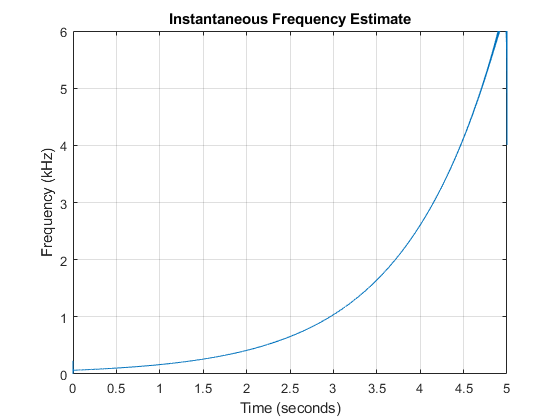

% Approximate the derivative of the unwrapped instantaneous phase
F = diff(unwrap(inst_phase));

% Plot it
plot(n(2:end)/Ts, F*10)
ylim([0, 6])
grid on
ylabel('Frequency (kHz)')
xlabel('Time (seconds)')
title('Instantaneous Frequency Estimate')

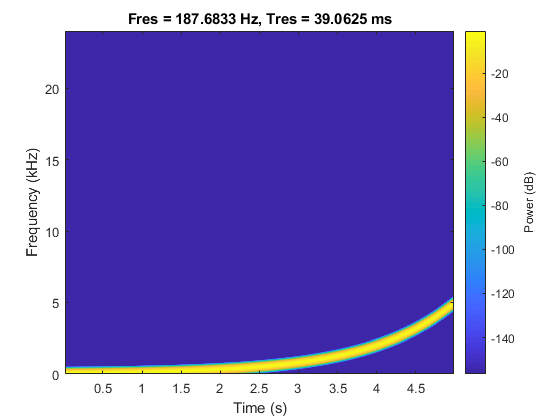

% Estimate the spectrogram of the waveform using the pspectrum function. 
pspectrum(s, Ts, 'spectrogram')

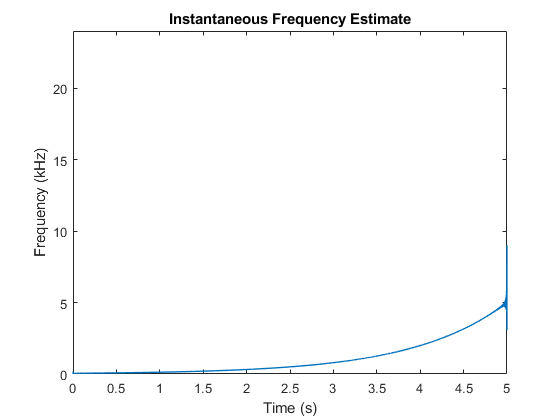


% The instfreq function computes and displays the instantaneous frequency in one step.
instfreq(s, Ts, 'Method', 'hilbert')

## [?] ADSI Problem 7.5: Envelope Detection

*The textbook states that the Hilbert transform can be used to find the envelope of a signal. The validity of this statement is investigated in this problem. *

*Consider an exponentially decaying oscillating signal given by*

        
$$x\left(n\right)=4e^{-0\ldotp 01n} \mathrm{cos}\left(\pi n\right)$$


clear variables;
clf

### [?] 1. Plot the signal and envelope on the same graph

*Plot this signal and use equation 9.4 to plot the envelope on the same graph. Compare the result with the expected outcome.*

The books states: If a real sinewave $x_r \left(t\right)$ is amplitude modulated so its envelope contains information, then we can measure the instantaneous envelope $E\left(t\right)$ values from an analytic version of the signal using the Equation 9-4:

        

Equation 9-4 states that the envelope of the signal is equal to magnitude of $x_c \left(t\right)$.

In MATLAB the complex magnitude of a signal can be computed with the `abs` function. 

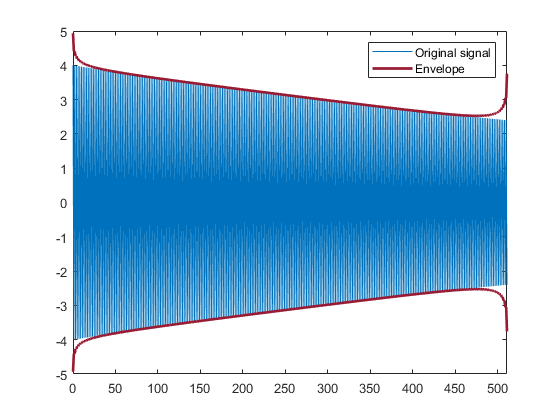

n = (0:511);
x_r = 4*exp(-0.001.*n).*cos(pi*n);

% Compute the analytic signal
x_c = hilbert(x_r);

% Find the envelope by computing the magnitude of the signal
x_envelope = abs(x_c);

% Plot the real signal
plot(n, x_r)
hold on

% Plot the envelope
plot(n, [-1;1]*x_envelope, 'Color', [0.6 0.1 0.2],'Linewidth',2)
hold off

legend('Original signal', 'Envelope')
xlim([0, max(n)])

### [✔] 2. Describe how noise affects Hilbert transform's ability to recover the envelope

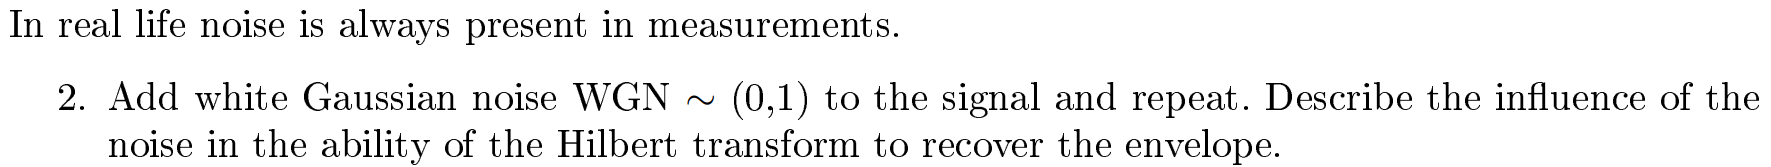

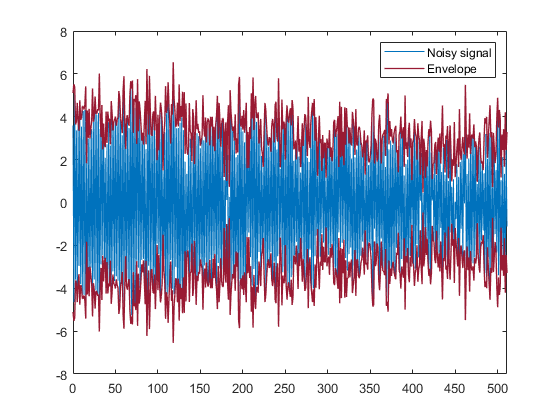

N = 512;
n = (0:N-1);
w = randn(N, 1)';
x_r = 4*exp(-0.001.*n).*cos(pi*n) + w;

x_c = hilbert(x_r);
x_envelope = abs(x_c);

plot(n, x_r)
hold on
plot(n, [-1;1]*x_envelope, 'Color', [0.6 0.1 0.2],'Linewidth',1)
hold off
legend('Noisy signal', 'Envelope')
xlim([0, max(n)])

Hilbert transform is sensitive to noise. We observe spurious peaks in the envelope due to noise.

We can generate a moving Root-Mean-Square (RMS) average envelopes by using a sliding window of size $W$. Using a large window size smooths out the envelope.

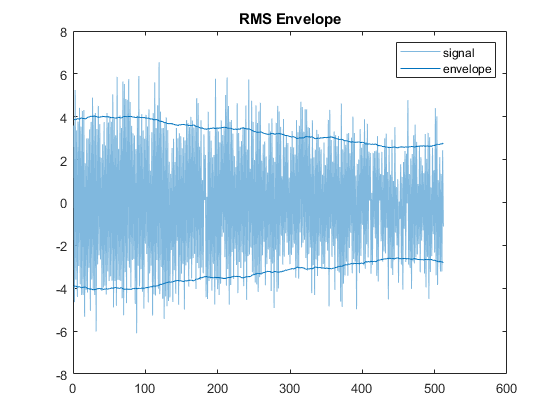

envelope(x_r, 100, 'rms');

### [✔] 3. Try with other two signals

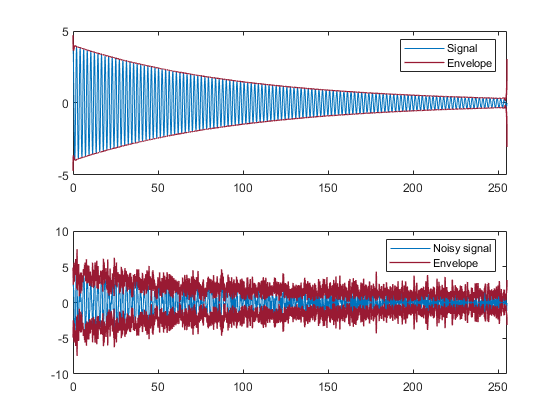

clear variables;

N = 256;
n = 0:0.1:N-1;
x = 4*exp(-0.01.*n).*cos(3*n);
plot_signal_and_envelope(n, x)

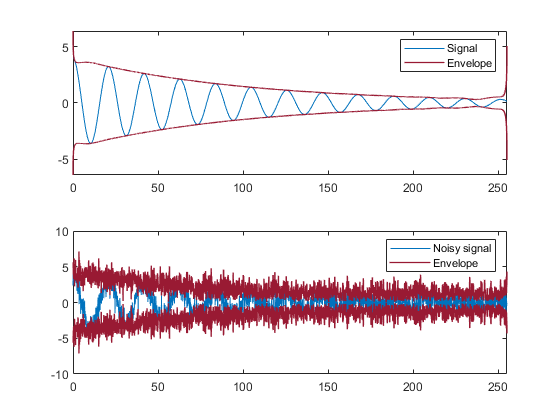

x = 4*exp(-0.01.*n).*cos(0.3*n);
plot_signal_and_envelope(n, x)

## [»] ADSI Problem 7.8: Amplitude modulated signal

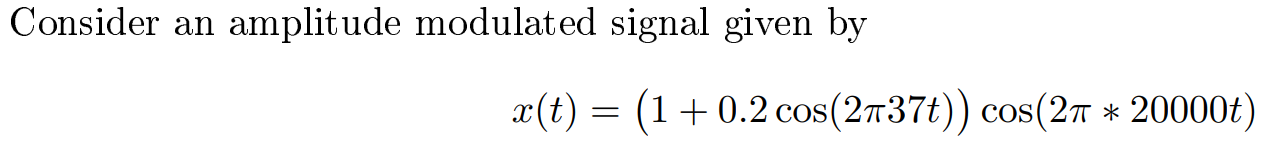

clear variables;

### [✔] 1. Plot 1 second of the signal and confirm that it is an amplitude modulated signal with a carrier frequency of 20 kHz.  

The discrete-time signal $x\left\lbrack n\right\rbrack$ of continuous-time signal $x\left(t\right)$ can be represented as:

        
$$x\left\lbrack n\right\rbrack =s\left(n\cdot T_s \right)$$
 

where 

- $n$ is an integer denoting the sample index 

- $T_s$ is the sampling period

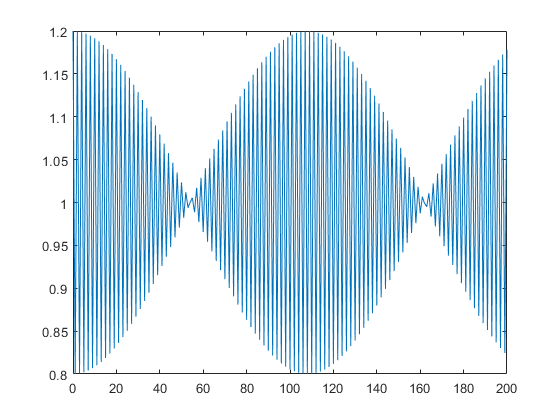

Ts = 8000; % Sampling rate
n = 0:200;
x = 1 + 0.2.*cos(2*pi*37*n/Ts).*cos(2*pi*20000*n/Ts);
plot(n, x)

### [»] 2. Use the procedure from Figure 9.8 in the note to frequency shift the signal to 15 kHz. Plot the spectrum of the signal at each step in the procedure.  

## Functions

function plot_signal_and_envelope(n, x)
w = randn(numel(n), 1)';
x_noisy = x + w;

x_c = hilbert(x);
x_envelope = abs(x_c);

x_noisy_c = hilbert(x_noisy);
x_noisy_envelope = abs(x_noisy_c);

clf
figure
ax1 = subplot(2,1,1);
plot(n, x)
hold on
plot(n, [-1;1]*x_envelope, 'Color', [0.6 0.1 0.2],'Linewidth',1)
hold off
legend('Signal', 'Envelope')
xlim([0, max(n)])

ax2 = subplot(2,1,2);
plot(n, x_noisy)
hold on
plot(n, [-1;1]*x_noisy_envelope, 'Color', [0.6 0.1 0.2],'Linewidth',1)
hold off
legend('Noisy signal', 'Envelope')
xlim([0, max(n)])
clear figure;
figure
end
